### Probability of Computational Latency Analysis

% Variables
datasize = 5000; % number of data points
epoch_time = 600; % 10 min in seconds
deadline_constraint = epoch_time / datasize;

% Value interval for Meshgrid
fluction_range = linspace(0, 0.8, 250);
maximum_range = linspace(0, 0.8, 250);

[Fluction, Maximum] = meshgrid(fluction_range, maximum_range);

% Calculation of exponential
Exponential = exp((-(Fluction .* deadline_constraint) ./ datasize) + (Fluction .* Maximum));
computational_latency_probability = 1 - Exponential;

% Create a colorData matrix
colorData = ones(size(computational_latency_probability));
colorData(computational_latency_probability >= 0 & computational_latency_probability <= 1) = 1;
colorData(computational_latency_probability < 0 | computational_latency_probability > 1) = 0;

% Graph
figure;
surf(Fluction, Maximum, computational_latency_probability, colorData, 'EdgeColor', 'none');
colormap([1 0 0; 0 0 1]); % [Red; Blue]
xlabel('Fluction Computation Capability');
ylabel('Maximum Computation Capability');
zlabel('Probability');
title('Probability of Computational Latency');

c = colorbar;
c.Ticks = [0 1];
c.TickLabels = {'Outside [0, 1]', 'Within [0, 1]'};

view([-27.618 38.240])


#### Comment-1:

Below parameters produces the graph shown. The problem is there is very limited zone that can provide the probability between 0 and 1.

fluction_range = linspace(-0.4, 0.8, 250);
maximum_range = linspace(-0.4, 0.8, 250);

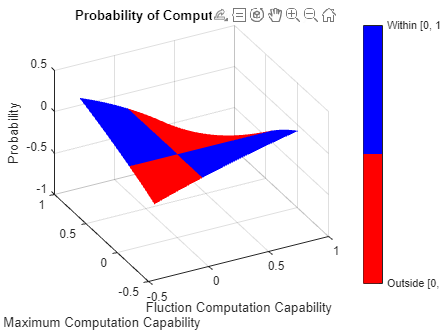

If the capability parameters are selected positive, which is expected in real life, no probability is in the interval. 

fluction_range = linspace(0, 0.8, 250);
maximum_range = linspace(0, 0.8, 250);